clc
clear
close all

## Data

G = 6.673*10^(-11); %Gravitational constant
Re = 6371*10^3;     %Earth Radius
Me = 5.972*10^24;   %Earth Mass
w = -7.272*10^(-5); %Earth Angular Velocity
h = 0.1;            %Time Interval

## Initial Condition For Fixed Frame(X,Y,Z)

(X) , (X_1=X': Velocity ) , (X_2=X'': Acceleration ) (Y) , (Y_1=Y': Velocity ) , (Y_2=Y'': Acceleration ) (Z) , (Z_1=Z': Velocity ) , (Z_2=Z'': Acceleration )

X = zeros(); X(1)=8000*10^3; %
Y = zeros(); Y(1)=8000*10^3; %% Initial Location
Z = zeros(); Z(1)=8000*10^3; %
X_1 = zeros(); X_1(1)=0; %
Y_1 = zeros(); Y_1(1)=0; %% Initial Velocity
Z_1 = zeros(); Z_1(1)=0; %
T = zeros();   T(1)=0;

X_2 = @(T,X,Y,Z) (-G*Me/(X.^2+Y.^2+Z.^2).^(3/2))*X; %
Y_2 = @(T,X,Y,Z) (-G*Me/(X.^2+Y.^2+Z.^2).^(3/2))*Y; %% Function
Z_2 = @(T,X,Y,Z) (-G*Me/(X.^2+Y.^2+Z.^2).^(3/2))*Z; %

## Runge Kutta Algorithm For Fixed Fram(X,Y,Z)

K = zeros(1,4);
L = zeros(1,4);
M = zeros(1,4);

k = zeros(1,4);
l = zeros(1,4);
m = zeros(1,4);

d = [1,2,2,1];

n = 1;
while sqrt(X(n).^2+Y(n).^2+Z(n).^2)>Re
    
    % FINDIG VELOCITY FROM ACCELERATION
    K(1)=X_2( T(n) , X(n) , Y(n) , Z(n) );
    L(1)=Y_2( T(n) , X(n) , Y(n) , Z(n) );
    M(1)=Z_2( T(n) , X(n) , Y(n) , Z(n) );
    
    K(2)=X_2( T(n)+h/2 , X(n)+h/2*K(1) , Y(n)+h/2*L(1) , Z(n)+h/2*M(1) );
    L(2)=Y_2( T(n)+h/2 , X(n)+h/2*K(1) , Y(n)+h/2*L(1) , Z(n)+h/2*M(1) );
    M(2)=Z_2( T(n)+h/2 , X(n)+h/2*K(1) , Y(n)+h/2*L(1) , Z(n)+h/2*M(1) );
    
    K(3)=X_2( T(n)+h/2 , X(n)+h/2*K(2) , Y(n)+h/2*L(2) , Z(n)+h/2*M(2) );
    L(3)=Y_2( T(n)+h/2 , X(n)+h/2*K(2) , Y(n)+h/2*L(2) , Z(n)+h/2*M(2) );
    M(3)=Z_2( T(n)+h/2 , X(n)+h/2*K(2) , Y(n)+h/2*L(2) , Z(n)+h/2*M(2) );
    
    K(4)=X_2( T(n)+h , X(n)+h*K(3) , Y(n)+h*L(3) , Z(n)+h*M(3) );
    L(4)=Y_2( T(n)+h , X(n)+h*K(3) , Y(n)+h*L(3) , Z(n)+h*M(3) );
    M(4)=Z_2( T(n)+h , X(n)+h*K(3) , Y(n)+h*L(3) , Z(n)+h*M(3) );
    
    X_1(n+1)=X_1(n) + h/6*sum(d.*K);
    Y_1(n+1)=Y_1(n) + h/6*sum(d.*L);
    Z_1(n+1)=Z_1(n) + h/6*sum(d.*M);
    
    
    
    % FINDIG LOCATION FROM VELOCITY
    k(1)=X_1(n);
    l(1)=Y_1(n);
    m(1)=Z_1(n);
    
    k(2)=X_1(n) + h/2*K(1);
    l(2)=Y_1(n) + h/2*L(1);
    m(2)=Z_1(n) + h/2*M(1);
    
    k(3)=X_1(n) + h/2*K(2);
    l(3)=Y_1(n) + h/2*L(2);
    m(3)=Z_1(n) + h/2*M(2);
    
    k(4)=X_1(n) + h*K(3);
    l(4)=Y_1(n) + h*L(3);
    m(4)=Z_1(n) + h*M(3);
    
    X(n+1)=X(n) + h/6*sum(d.*k);
    Y(n+1)=Y(n) + h/6*sum(d.*l);
    Z(n+1)=Z(n) + h/6*sum(d.*m);
    
    T(n+1)=T(n)+h;
    n=n+1;
    
end

## Initial Condition For Moving Frame(x,y,z)

(x) , (x_1=x': Velocity ) , (x_2=x'': Acceleration ) (y) , (y_1=y': Velocity ) , (y_2=y'': Acceleration ) (z) , (z_1=z': Velocity ) , (z_2=z'': Acceleration )

x = zeros(); x(1)=8000*10^3; %
y = zeros(); y(1)=8000*10^3; %% Initial Location
z = zeros(); z(1)=8000*10^3; %
x_1 = zeros(); x_1(1)=0; %
y_1 = zeros(); y_1(1)=0; %% Initial Velocity
z_1 = zeros(); z_1(1)=0; %
t = zeros();   t(1)=0;

x_2 = @(t,x,x_1,y,y_1,z) (-G*Me/(x.^2+y.^2+z.^2).^(3/2) + w^2)*x + 2*w*y_1; %
y_2 = @(t,x,x_1,y,y_1,z) (-G*Me/(x.^2+y.^2+z.^2).^(3/2) + w^2)*y - 2*w*x_1; %% Function
z_2 = @(t,x,x_1,y,y_1,z) (-G*Me/(x.^2+y.^2+z.^2).^(3/2))*z;                 %

## Runge Kutta Algorithm For Moving Frame(x,y,z)

A = zeros(1,4);
B = zeros(1,4);
C = zeros(1,4);

a = zeros(1,4);
b = zeros(1,4);
c = zeros(1,4);

d = [1,2,2,1];

n = 1;
while sqrt(x(n).^2+y(n).^2+z(n).^2)>Re
    
    % FINDIG VELOCITY FROM ACCELERATION
    A(1)=x_2( t(n) , x(n) , x_1(n) , y(n) , y_1(n) , z(n) );
    B(1)=y_2( t(n) , x(n) , x_1(n) , y(n) , y_1(n) , z(n) );
    C(1)=z_2( t(n) , x(n) , x_1(n) , y(n) , y_1(n) , z(n) );
    
    A(2)=x_2( t(n)+h/2 , x(n)+h/2*A(1) , x_1(n)+h/2*A(1) , y(n)+h/2*B(1) , y_1(n)+h/2*B(1) , z(n)+h/2*C(1) );
    B(2)=y_2( t(n)+h/2 , x(n)+h/2*A(1) , x_1(n)+h/2*A(1) , y(n)+h/2*B(1) , y_1(n)+h/2*B(1) , z(n)+h/2*C(1) );
    C(2)=z_2( t(n)+h/2 , x(n)+h/2*A(1) , x_1(n)+h/2*A(1) , y(n)+h/2*B(1) , y_1(n)+h/2*B(1) , z(n)+h/2*C(1) );
    
    A(3)=x_2( t(n)+h/2 , x(n)+h/2*A(2) , x_1(n)+h/2*A(2) , y(n)+h/2*B(2) , y_1(n)+h/2*B(2) , z(n)+h/2*C(2) );
    B(3)=y_2( t(n)+h/2 , x(n)+h/2*A(2) , x_1(n)+h/2*A(2) , y(n)+h/2*B(2) , y_1(n)+h/2*B(2) , z(n)+h/2*C(2) );
    C(3)=z_2( t(n)+h/2 , x(n)+h/2*A(2) , x_1(n)+h/2*A(2) , y(n)+h/2*B(2) , y_1(n)+h/2*B(2) , z(n)+h/2*C(2) );
    
    A(4)=x_2( t(n)+h , x(n)+h*A(3) , x_1(n)+h*A(3) , y(n)+h*B(3) , y_1(n)+h*B(3) , z(n)+h*C(3) );
    B(4)=y_2( t(n)+h , x(n)+h*A(3) , x_1(n)+h*A(3) , y(n)+h*B(3) , y_1(n)+h*B(3) , z(n)+h*C(3) );
    C(4)=z_2( t(n)+h , x(n)+h*A(3) , x_1(n)+h*A(3) , y(n)+h*B(3) , y_1(n)+h*B(3) , z(n)+h*C(3) );
    
    x_1(n+1)=x_1(n) + h/6*sum(d.*A);
    y_1(n+1)=y_1(n) + h/6*sum(d.*B);
    z_1(n+1)=z_1(n) + h/6*sum(d.*C);
    
    
    
    % FINDIG LOCATION FROM VELOCITY
    a(1)=x_1(n);
    b(1)=y_1(n);
    c(1)=z_1(n);
    
    a(2)=x_1(n) + h/2*A(1);
    b(2)=y_1(n) + h/2*B(1);
    c(2)=z_1(n) + h/2*C(1);
    
    a(3)=x_1(n) + h/2*A(2);
    b(3)=y_1(n) + h/2*B(2);
    c(3)=z_1(n) + h/2*C(2);
    
    a(4)=x_1(n) + h*A(3);
    b(4)=y_1(n) + h*B(3);
    c(4)=z_1(n) + h*C(3);
    
    x(n+1)=x(n) + h/6*sum(d.*a);
    y(n+1)=y(n) + h/6*sum(d.*b);
    z(n+1)=z(n) + h/6*sum(d.*c);
    
    t(n+1)=t(n)+h;
    n=n+1;
    
end
r = sqrt(x.^2+y.^2+z.^2);

## Result & Plot

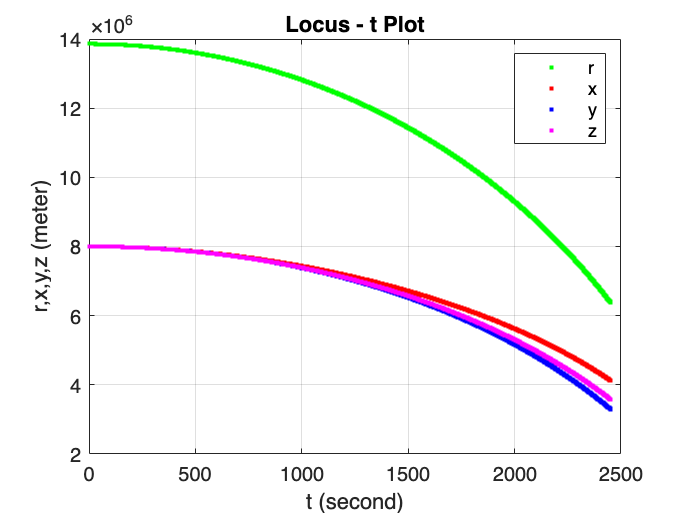

figure(1);plot(t,r,'.g',t,x,'.r',t,y,'.b',t,z,'.m');grid
xlabel('t (second)'); ylabel('r,x,y,z (meter)')
legend('r','x','y','z'); title('Locus - t Plot');

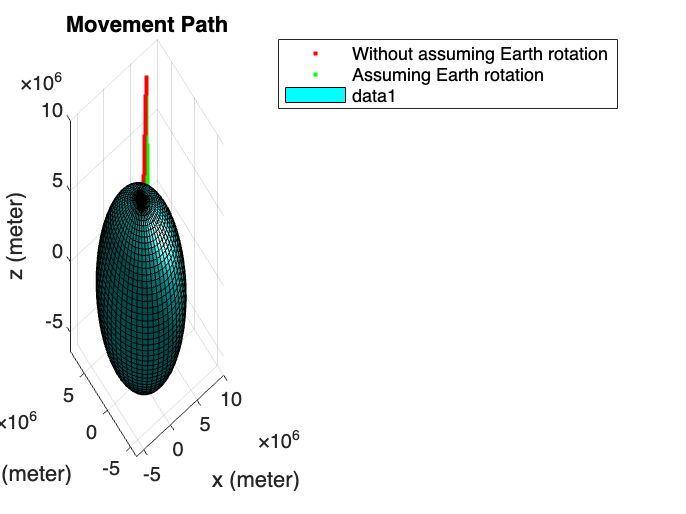


figure(2);plot3(X,Y,Z,'.r',x,y,z,'.g');grid
xlabel('x (meter)'); ylabel('y (meter)'); zlabel('z (meter)');
legend('Without assuming Earth rotation','Assuming Earth rotation'); title('Movement Path');

hold on

[X,Y,Z]=sphere(50);
X = X*Re; Y = Y*Re; Z = Z*Re;
surf(X,Y,Z,'facecolor',[0 1 1]);light;